# **整体优化**

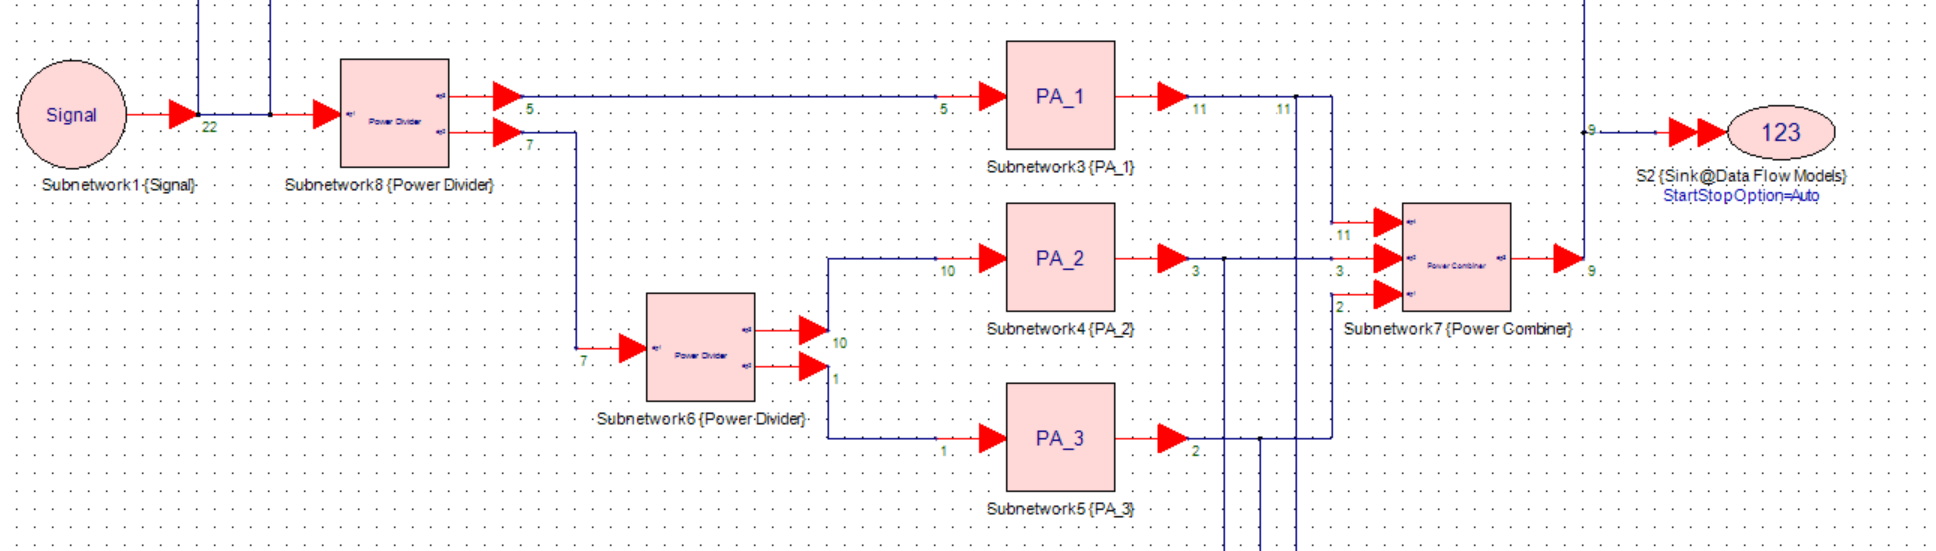

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Original System----------------------------

此模型是完全固定的！

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile();
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Original_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 
% 模型仿真
[A1_input,A23]=Power_Divider(Sys_input);
[A2_input,A3_input]=Power_Divider(A23);
A1_output=PA_1(A1_input);
A2_output=PA_2(A2_input);
A3_output=PA_3(A3_input);
Original_output_sim=Power_Combiner(A1_output,A2_output,A3_output);
% 性能评估
err=abs(Original_output_sim-Original_output) %模型本身的误差

err = 1.0e-14 *

    0.0171
    0.0450
    0.0623
    0.0124
    0.0056
    0.0395
    0.0420
    0.0776
    0.0072
    0.0168


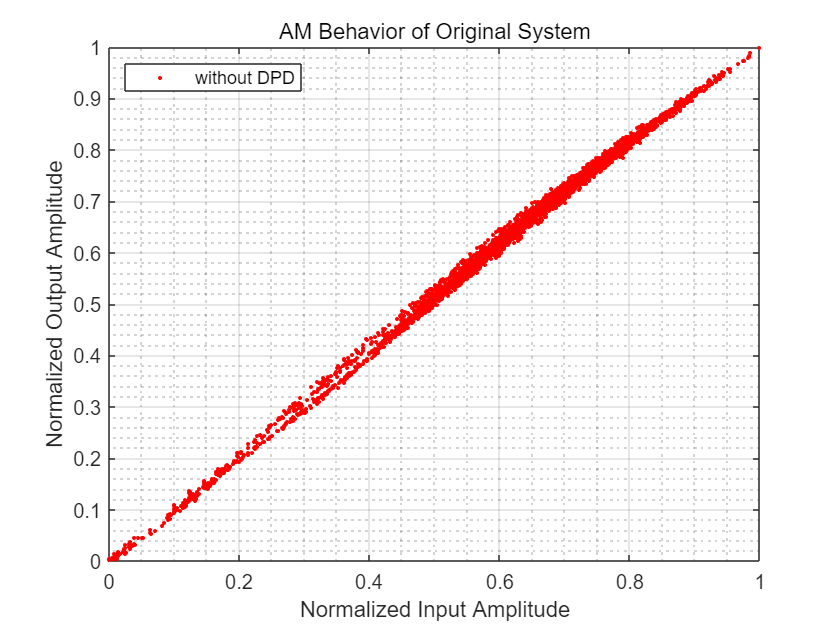

Plot_AM(Sys_input,Original_output_sim,'AM Behavior of Original System','without DPD');

nmse_sim= NMSE_dB(Sys_input,Original_output_sim);
nmse_act = NMSE_dB(Sys_input,Original_output);
fprintf('不使用DPD，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

不使用DPD，系统的NMSE仿真结果为 -26.743435 dB


fprintf('不使用DPD，系统的NMSE实测结果为 %f dB\n', nmse_act);

不使用DPD，系统的NMSE实测结果为 -26.743435 dB


## -----------------------------Model B System----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Sys_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 

## 整体训练(训练一次即可)

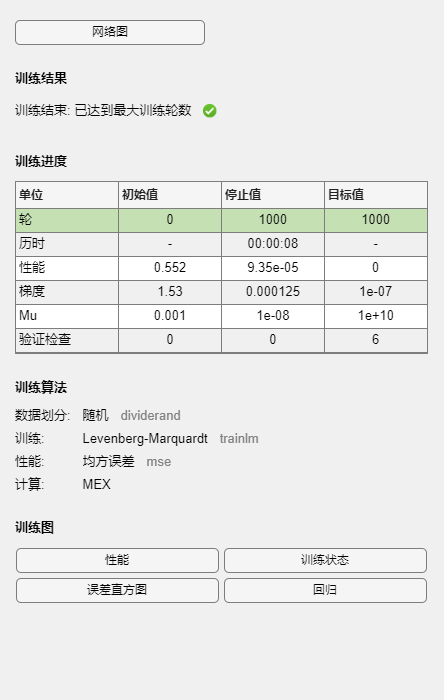

% 参数需要保持一致
M = 2; 
% Adjust Parameters and Train Models
net = feedforwardnet(5); 
[model_input,model_output] = pre_train(M,real(Sys_input),imag(Sys_input),real(Sys_output),imag(Sys_output),dim);
model = train(net, model_input, model_output);

save('Method_B\Whole\FNN.mat', 'model');

## Model Test

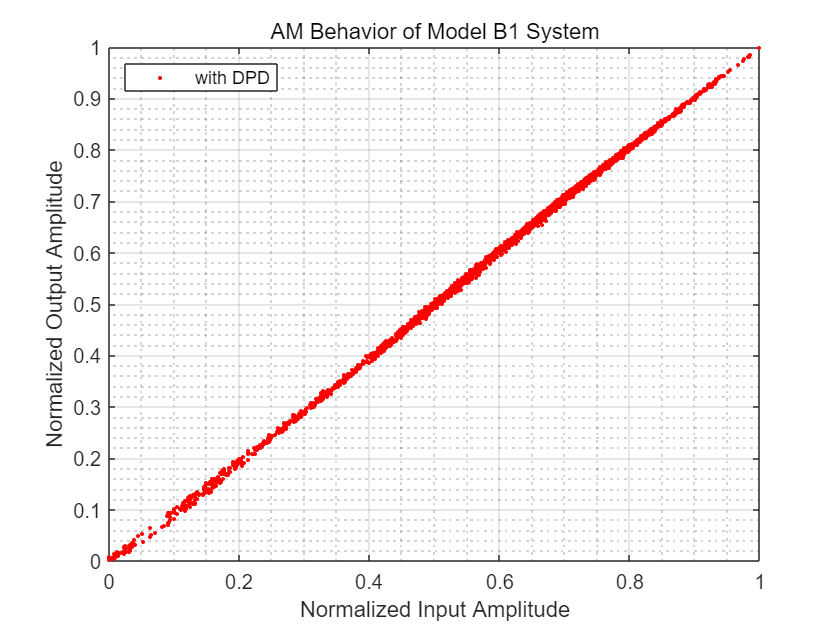

% 参数需要保持一致
M = 2;
% 系统模拟
Sys_input_DPD=DPD_Whole(Sys_input,M,'Method_B\Whole\FNN.mat');
% 模型仿真
[A1_input,A23]=Power_Divider(Sys_input_DPD);
[A2_input,A3_input]=Power_Divider(A23);
A1_output=PA_1(A1_input);
A2_output=PA_2(A2_input);
A3_output=PA_3(A3_input);
Sys_output_sim=Power_Combiner(A1_output,A2_output,A3_output);

% 性能评估
Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Model B1 System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model B，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model B，系统的NMSE仿真结果为 -36.837334 dB
